# Particle Swarm Optimization

- meta heuristic algorithm

- contains a population of candidate solutions

- particle i position -> xi(t) where xi(t) is a vector in the set of X

- particle i velocity -> vi(t) 

- particle i memory -> pi(t) where pi(t) is the best solution for particle i

- g(t) is the common swarm experience, no i

## Particle Update Functions

- vi(t+1) = a*vi(t) + b*(pi(t) -xi(t)) + c*(g(t) - xi(t))

- xi(t+1) = xi(t) + vi(t+1)

- vij(t+1) = inertia + cognitive + social where vij is the jth scalar

- xij(t+1) = xij(t) + vij(t+1)

% EXAMPLE
%
% inertia = coef*velocity(i,j);
% cognitive = rand()*accel1*(particleBest(i,j) - particlePos(i,j));
% social = rand()*accel2*(globalBest(j) - particlePos(i,j));

## The Problem

- The sphere function

- [http://benchmarkfcns.xyz/benchmarkfcns/spherefcn.html](http://benchmarkfcns.xyz/benchmarkfcns/spherefcn.html) 

## The Algorithm

- problem definition

% define the cost function
costFcn = @(x) sphere(x);

% number of unknown variables
numParams = 5;

% matrix size of solutions
size = [1 numParams];

% variable range
varMin = -10;
varMax = 10;

- parameters

% number of iterations
iterations = 100;

% number of particles
swarmSize = 50;

% inertia coefficient
w = 1;
b = .99; %damping ratio

% max velocity
v = .2

v = 0.2000

maxV = v*(varMax - varMin);
minV = -maxV;

% personal acceleration coefficient
accel1 = 2;

% social acceleration coefficient
accel2 = 2;

- initialization 

% initialize the particle fields
particle.position  = [];
particle.velocity  = [];
particle.cost      = [];
particle.best.pos  = [];
particle.best.cost = [];

% initialize swarm best
swarmBest.cost = inf;

% initialize best cost vector
bestCosts = zeros(iterations, 1);

% initialize an empty population
particles = repmat(particle, swarmSize, 1);

% initialize the particle fields
for i=1:swarmSize
    % random position
    particles(i).position = unifrnd(varMin, varMax, 1, numParams);
    
    % zero velocity
    particles(i).velocity = zeros(1, numParams);
    
    % evaluate the particles position
    particles(i).cost = costFcn(particles(i).position);
    
    % particle best
    particles(i).best.position = particles(i).position;
    particles(i).best.cost = particles(i).cost;
    
    % swarm best
    if particles(i).best.cost < swarmBest.cost
        swarmBest = particles(i).best;
    end

end

- main loop

for it=1:iterations
    % for each particle in the swarm
    for i=1:swarmSize
        % update its velocity
        particles(i).velocity = w*particles(i).velocity ...
            + accel1*rand(1,numParams).*(particles(i).best.position - particles(i).position) ...
            + accel2*rand(1,numParams).*(swarmBest.position - particles(i).position);
        
        % apply velocity bounds
        particles(i).velocity = max(particles(i).velocity, minV);
        particles(i).velocity = min(particles(i).velocity, maxV);
            
            
        % update its position          
        particles(i).position = particles(i).position + particles(i).velocity; 
       
        % apply position bounds
        particles(i).position = max(particles(i).position, varMin);
        particles(i).position = min(particles(i).position, varMax);
        
        % update its cost
        particles(i).cost = costFcn(particles(i).position);
        
        % update its personal best
        if particles(i).cost < particles(i).best.cost
            particles(i).best.position = particles(i).position;
            particles(i).best.cost = particles(i).cost;
            
            % update its global best
            if particles(i).best.cost < swarmBest.cost
                swarmBest = particles(i).best;
            end
        end
    end
        
    % update inertia
    w = w*b;
    
    % update best cost for the iteration
    bestCosts(it) = swarmBest.cost;
    
    %disp(['iteration ' num2str(it) ': best cost: ' num2str(bestCosts(it))]);
end
disp(['iteration ' num2str(it) ': best cost: ' num2str(bestCosts(it))]);

iteration 100: best cost: 7.5051e-06


- plot the convergence

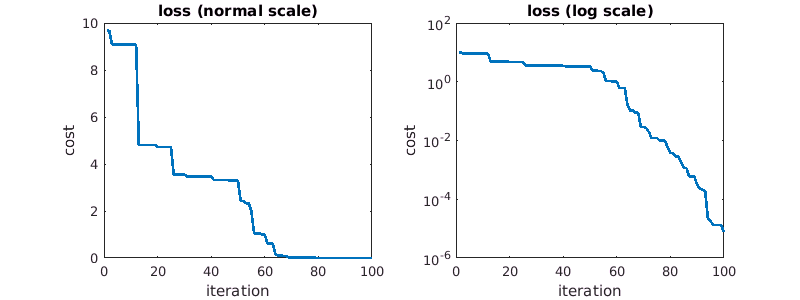

f1 = figure(1); clf;
f1.Position = [0 0 800 300];
subplot(121);
plot(bestCosts, 'linew', 2);
xlabel('iteration');
ylabel('cost');
title('loss (normal scale)');

subplot(122);
semilogy(bestCosts, 'linew', 2);
xlabel('iteration');
ylabel('cost');
title('loss (log scale)');

## Functions

sphere:

- the function to optimize

function z = sphere(x)
    z = sum(x.^2);
end






